%% ==== 简单MPC路径规划仿真 - USV局部避障演示（带水流扰动+动态参考航向角版） ====
clear; clc; close all;

%% 参数设定
dt = 0.2;         % 控制周期
N = 25;           % 预测步数
sim_time = 600;    % 仿真总时间
steps = sim_time / dt;

% 起点终点
start = [0, 0];
goal  = [50, 50];

% 扩展目标状态 [X, Y, theta, u, v, omega]
goal_state = [goal(1), goal(2), 0, 5.0, 0.0, 0.0]; % 目标速度设5m/s，航向初设0°

% 障碍物（两个矩形）
obstacles = {
    [20, 20; 30, 20; 30, 30; 20, 30];
    [35, 40; 45, 40; 45, 50; 35, 50]
};

% USV初始状态 [X, Y, theta, u, v, omega]
state = [start, 0, 0, 0, 0];
trajectory = zeros(steps + 1, 6);  % 预分配轨迹矩阵（行数 = 仿真步长 + 初始点）
trajectory(1, :) = state;         % 第1行存初始状态

% ==== 水流初始化 ====
V_current = 0.5;                 % 初始水流速度 (m/s)
psi_current = pi/4;    % 初始水流方向 (0~2pi)

%% ==== MPC仿真主循环 ====
for t = 1:steps

% ==== 水流扰动模拟 ====
if rand() < 0.01
    V_current = V_current + (rand()*0.1 - 0.05); % ΔV ∈ [-0.05, 0.05]
    psi_current = psi_current + (rand()*0.05 - 0.025); % Δψ ∈ [-0.025, 0.025]
    V_current = max(0.0, min(3.0, V_current));

    % === 限制水流角度在 [0°, 60°] 范围 ===
     psi_current = max(0, min(pi/3, psi_current));  
end

    % ==== 调用MPC控制器 ====
    u = mpc_controller(state, goal_state, obstacles, N, dt, V_current, psi_current);

    % ==== USV状态更新（考虑水流） ====
    state(4) = state(4) + u(1) * dt;  % surge
    state(5) = state(5) + u(2) * dt;  % sway
    state(6) = state(6) + u(3) * dt;  % yaw rate

    % 计算合速度（加上水流）
    Xdot = state(4) * cos(state(3)) - state(5) * sin(state(3));
    Ydot = state(4) * sin(state(3)) + state(5) * cos(state(3));
    Xdot = Xdot + V_current * cos(psi_current);
    Ydot = Ydot + V_current * sin(psi_current);

    % 更新位置
    state(1) = state(1) + Xdot * dt;
    state(2) = state(2) + Ydot * dt;
    state(3) = state(3) + state(6) * dt;

    trajectory(t + 1, :) = state;

    % ==== 新增：检查是否到达目标 ====
    distance_to_goal = norm(state(1:2) - goal_state(1:2));
    if distance_to_goal < 1 

        disp(['USV成功到达目标点，仿真在第 ' num2str(t*dt) ' 秒停止。']);
    break;
    end
end

USV成功到达目标点，仿真在第 108 秒停止。


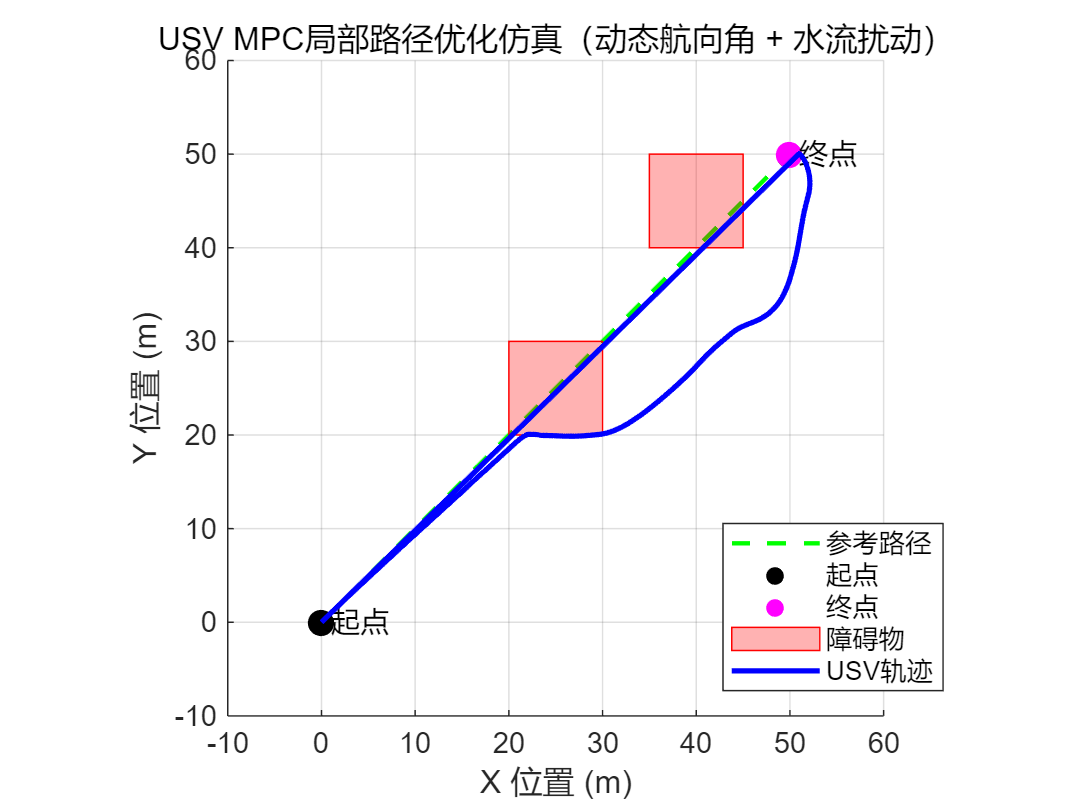


%% ==== 可视化轨迹 ====
figure; hold on; grid on;
title('USV MPC局部路径优化仿真（动态航向角 + 水流扰动）');
xlabel('X 位置 (m)'); ylabel('Y 位置 (m)');

% 绘制参考路径
plot([start(1), goal(1)], [start(2), goal(2)], 'g--', 'LineWidth', 1.5, 'DisplayName', '参考路径');

% 起点终点
scatter(start(1), start(2), 80, 'k', 'filled', 'DisplayName', '起点');
text(start(1)+1, start(2), '起点');
scatter(goal(1), goal(2), 80, 'm', 'filled', 'DisplayName', '终点');
text(goal(1)+1, goal(2), '终点');

% 绘制障碍物（只显示一个图例）
for i = 1:length(obstacles)
    obs = obstacles{i};
    if i == 1
        fill(obs(:,1), obs(:,2), 'r', 'FaceAlpha', 0.3, ...
            'EdgeColor', 'r', 'DisplayName', '障碍物');
    else
        fill(obs(:,1), obs(:,2), 'r', 'FaceAlpha', 0.3, ...
            'EdgeColor', 'r', 'HandleVisibility', 'off');
    end
end


% 绘制 USV轨迹线（不进图例）
plot(trajectory(:,1), trajectory(:,2), 'b-', 'LineWidth', 1.8, 'HandleVisibility', 'off');

% 创建虚拟蓝色实线用于图例
plot(nan, nan, 'b-', 'LineWidth', 1.8, 'DisplayName', 'USV轨迹');

% 设置图例
legend('Location','best');
axis equal;
xlim([-10, 60]); ylim([-10, 60]);